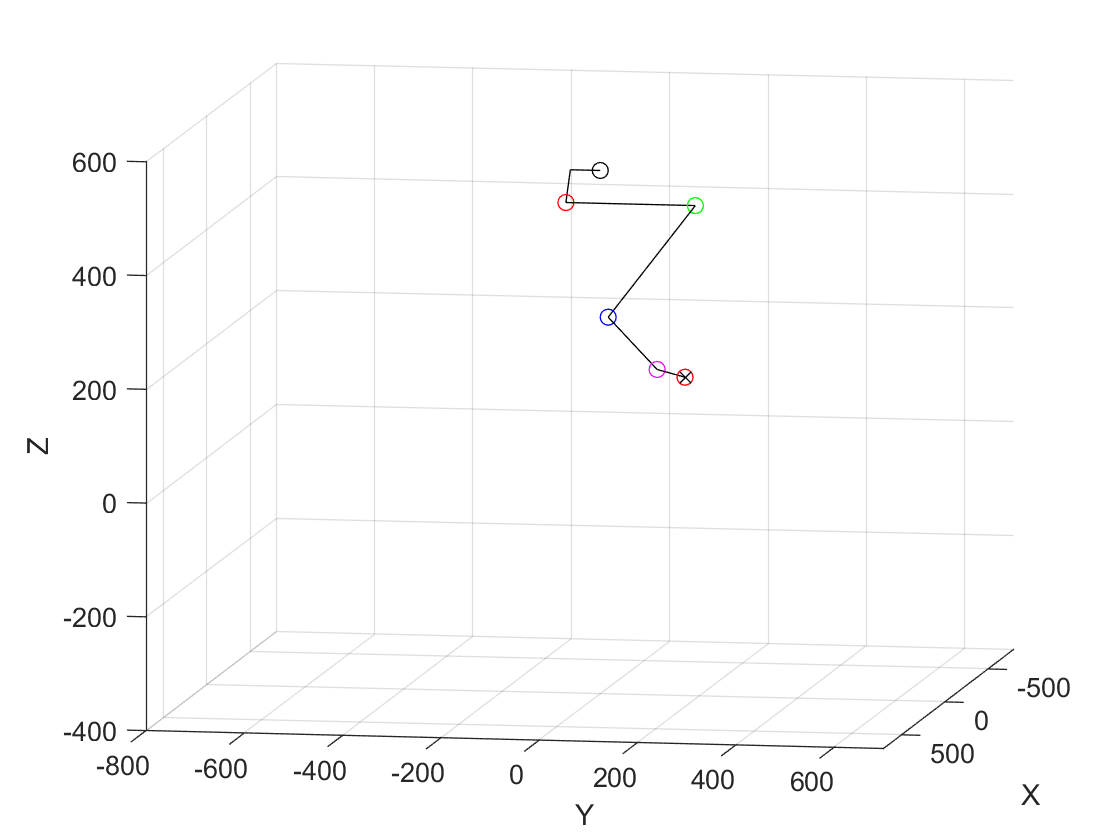

close all
clear
clc

pi=sym(pi);  

physicalProportions;

% Statring actuator angles
theta2 = pi/4;
theta3 = pi/2;
theta4 = -120*pi/180;
theta5 = 75*pi/180;

d       = [0 hipLength 0 0 0 0 phalangesLength-24];                 % z-offset (-24mm to plce the end-efector in the middle of the physical foot)
theta   = [0 theta2+hipRotation theta3 theta4 theta5 -pi/3 0];      % z-rotation, actuator angles
a       = [0 hipHeigth femurLength tibiaLength tarsalLength 0 0];   % x-offset
alpha   = [baseRotation hipRotation 0 0 0 -pi/2 0];                 % x-rotation               % x-rotation
linkType = ["rot" "rot" "rot" "rot" "rot" "rot" "rot"];             % Type of rotation for the Jacobi-matrix

n = length(d);                                                      % degrees of freedom + base rotation and end efector angle

A = symCalcA(a, alpha, d, theta, n);
T = symCalcT(A,n);

% Plot robot in starting positions
figure();
plotRobot(T, n, baseHeight);

% Direct kinematics from trigonometry
delta = pi/2+theta(6); %Theta(6) is allready negative so we use + here
r = a(2)+a(3)*cos(theta(3))+a(4)*cos(theta(3)+theta(4))+a(5)*cos(theta(3)+theta(4)+theta(5))+d(7)*cos(theta(3)+theta(4)+theta(5)+delta);
x = r*sin(theta2);
z = -r*cos(theta2)+baseHeight;
y = -d(2)+a(3)*sin(theta(3))+a(4)*sin(theta(3)+theta(4))+a(5)*sin(theta(3)+theta(4)+theta(5))+d(7)*sin(theta(3)+theta(4)+theta(5)+delta);

plot3(x,y,z,'kx');

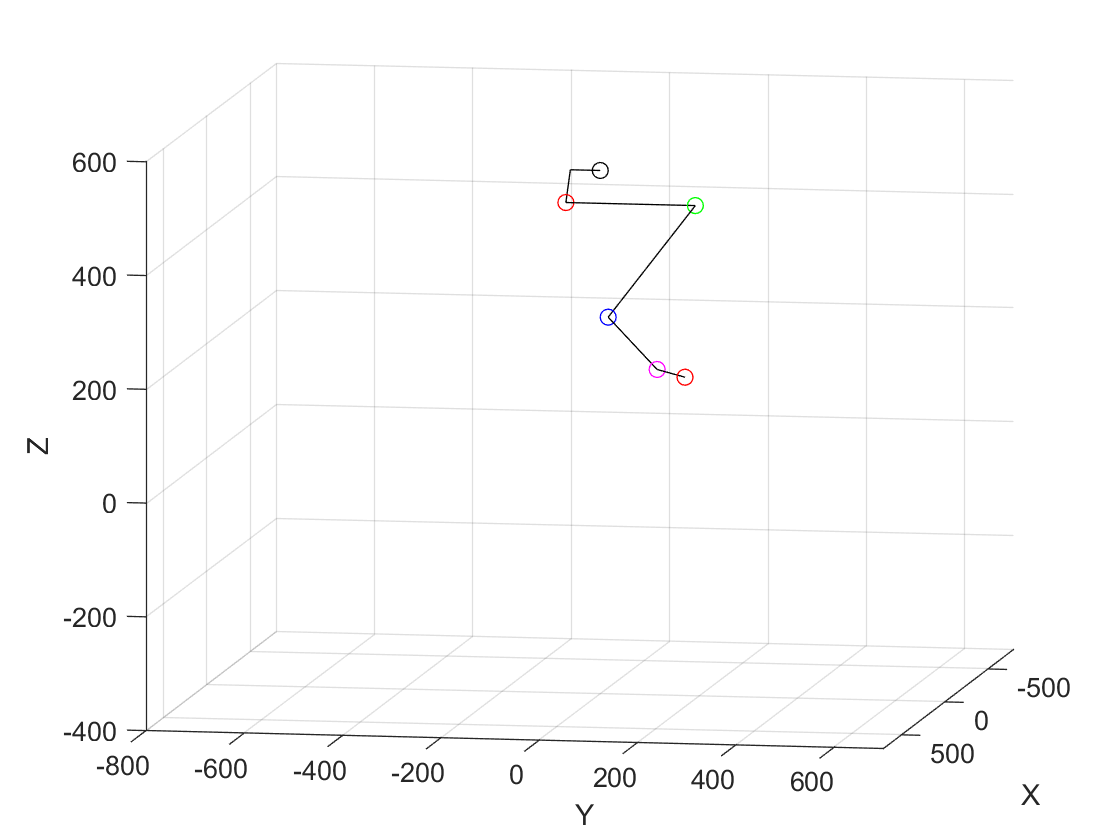


% Inverse kinematics from trigonometry
x = x;
y = y;
z = z - baseHeight;
phi = -(theta(3)+theta(4)+theta(5)+theta(6));

theta(2) = atan2(x,-z)+hipRotation;
r = sqrt(x^2+z^2);

ym = y+d(2)+a(5)*sin(phi+theta(6))-d(7)*sin(pi/2-phi);
rm = r-a(2)-a(5)*cos(phi+theta(6))-d(7)*cos(pi/2-phi);

gamma = atan2(-ym/sqrt(rm^2+ym^2),-rm/sqrt(rm^2+ym^2));

theta(3) = gamma - acos(-(rm^2+ym^2+a(3)^2-a(4)^2)/(2*a(3)*sqrt(rm^2+ym^2)));
theta(4) = atan2((ym-a(3)*sin(theta(3)))/a(4),(rm-a(3)*cos(theta(3)))/a(4))-theta(3);
theta(5) = -(phi+theta(3)+theta(4)+theta(6));

n = length(d);                                                      % degrees of freedom + base rotation and end efector angle
A = symCalcA(a, alpha, d, theta, n);
T = symCalcT(A,n);

figure();
plotRobot(T, n, baseHeight);


% Alt Jacobi test
syms theta2 theta3 theta4 theta5
syms dtheta2 dtheta3 dtheta4 dtheta5
%syms x y z phi

delta = pi/2+theta(6); %Theta(6) is allready negative so we use + here
r = a(2)+a(3)*cos(theta3)+a(4)*cos(theta3+theta4)+a(5)*cos(theta3+theta4+theta5)+d(7)*cos(theta3+theta4+theta5+delta);
x = r*sin(theta2);
z = -r*cos(theta2)+baseHeight;
y = -d(2)+a(3)*sin(theta3)+a(4)*sin(theta3+theta4)+a(5)*sin(theta3+theta4+theta5)+d(7)*sin(theta3+theta4+theta5+delta);

q = [theta2; theta3; theta4; theta5];
dq = [dtheta2; dtheta3; dtheta4; dtheta5];
p = [x;y;z];

dp = jacobian(p,q)*dq;
